# Exploring the Experiment's Design

In this set of exercises, we'll get our first look at the experiment we'll be analyzing in this course; curated data from the [Steinmetz et al, 2019](https://www.nature.com/articles/s41586-019-1787-x) paper.

Today's data is focused on three CSV files, each containing sessions  from a different stretch of data collection.  They contain trial-level  data from the experiment:

- steinmetz_winter2016.csv

- steinmetz_summer2017.csv

- steinmetz_winter2017.csv

## Loading and viewing data

Let's load in some csv data with MATLAB and see what we have!

`Download datafiles`

cwd = fileparts(matlab.desktop.editor.getActiveFilename);
url= "https://uni-bonn.sciebo.de/s/9FxelLhARmHpw85";
mkdir(strcat(cwd,'/data'));

websave(strcat(cwd,'/data/testfile.csv'), strcat(url, '/download') );

**Example: **

Load in the winter 2016 dataset and view the first 5 rows of the data

data = readtable('./data/steinmetz_winter2016.csv');
data(1:5,:)

ans = 5×15 table
    trial    active_trials    contrast_left    contrast_right    stim_onset    gocue_time    response_type    response_time    feedback_time    feedback_type    reaction_time    reaction_type     mouse      session_date    session_id
    _____    _____________    _____________    ______________    __________    __________    _____________    _____________    _____________    _____________    _____________    _____________    ________    ____________    __________

    

The variable data is a MATLAB table, we can see that in the Workspace pannel on the right.

**Exercises**

Load in the summer 2016 dataset and view the first 10 rows of the data

How many rows are in the summer 2016 dataset?

height(data)

ans = 3767

How many columns are in the summer 2016 dataset?

width(data)

ans = 15

What are the column names in the summer 2016 dataset?

data.Properties.VariableNames

ans = 1×15 cell array
    {'trial'}    {'active_trials'}    {'contrast_left'}    {'contrast_right'}    {'stim_onset'}    {'gocue_time'}    {'response_type'}    {'response_time'}    {'feedback_time'}    {'feedback_type'}    {'reaction_time'}    {'reaction_type'}    {'mouse'}    {'session_date'}    {'session_id'}


## Experiment Description: Calculating Statistics on Continuous Data

## Experiment Description: Calculating Statistics of Across Categorical Data

## Visualizing the Experimental Design using Plots

unique(data.session_date) % Note Matlab autoconverted session_dates to datetime!

ans = 9×1 datetime array
   14-Dec-2016
   17-Dec-2016
   18-Dec-2016
   07-Jan-2017
   08-Jan-2017
   09-Jan-2017
   10-Jan-2017
   11-Jan-2017
   12-Jan-2017



trials_by_date = groupcounts(data,"session_date","day")

trials_by_date = 9×3 table
    day_session_date    GroupCount    Percent
    ________________    __________    _______

      14-Dec-2016          364        9.6629 
      17-Dec-2016          401        10.645 
      18-Dec-2016          378        10.035 
      07-Jan-2017          554        14.707 
      08-Jan-2017          632        16.777 
      09-Jan-2017          585         15.53 
      10-Jan-2017          363        9.6363 
      11-Jan-2017          252        6.6897 
      12-Jan-2017          238         6.318 


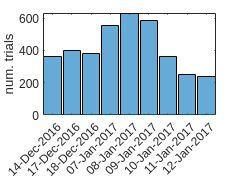


histogram('Categories', unique(trials_by_date.day_session_date ),'BinCounts', trials_by_date.GroupCount)
ylabel('num. trials')

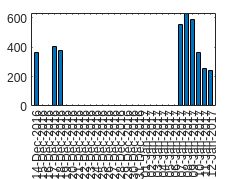

bar( unique(trials_by_date.day_session_date ), trials_by_date.GroupCount)

fileparts(matlab.desktop.editor.getActiveFilename)

ans = '/home/ben/ibots/python_2_matlab/matlab/day1'